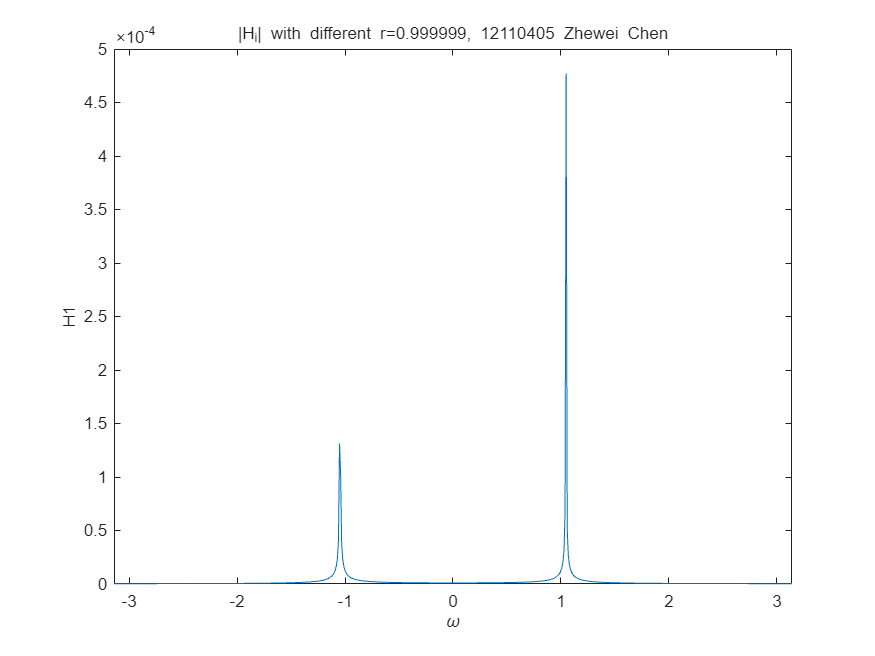

clc;clear;close all;
w1=-pi:0.01:pi;
z=exp(1i*w1);
r1=0.999999;
r2=0.9;
r3=0.7;
H1=(1-r1)./(1-2*r1*cos(pi/3).*z.^(-1)+r1.^2.*z.^(-2));
H2=(1-r2)./(1-2*r2*cos(pi/3).*z.^(-1)+r2.^2.*z.^(-2));
H3=(1-r3)./(1-2*r3*cos(pi/3).*z.^(-1)+r3.^2.*z.^(-2));
figure;
plot(w1,abs(H1));xlabel('\omega','FontSize',10);ylabel('H1','FontSize',10);title('|H_{i}| with different r=0.999999, 12110405 Zhewei Chen','FontSize',10);xlim([-pi,pi])

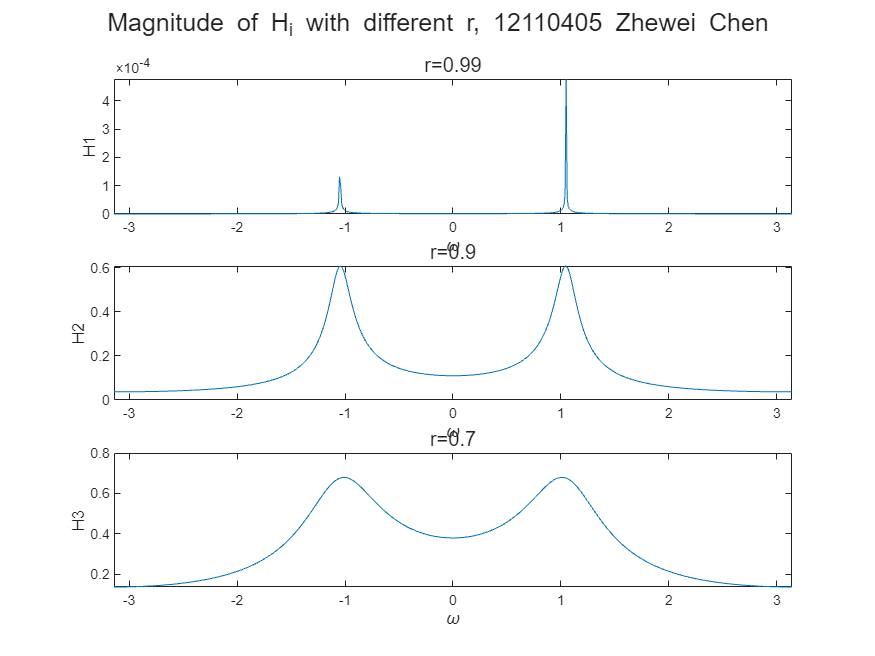

figure;
sgtitle('Magnitude of H_i with different r, 12110405 Zhewei Chen')
subplot(311);
plot(w1,abs(H1));xlabel('\omega','FontSize',10);ylabel('H1','FontSize',10);title('r=0.99','FontSize',12);xlim([-pi,pi])
subplot(312);
plot(w1,abs(H2));xlabel('\omega','FontSize',10);ylabel('H2','FontSize',10);title('r=0.9','Fontsize',12);xlim([-pi,pi])
subplot(313);
plot(w1,abs(H3));xlabel('\omega','FontSize',10);ylabel('H3','FontSize',10);title('r=0.7','Fontsize',12);xlim([-pi,pi])

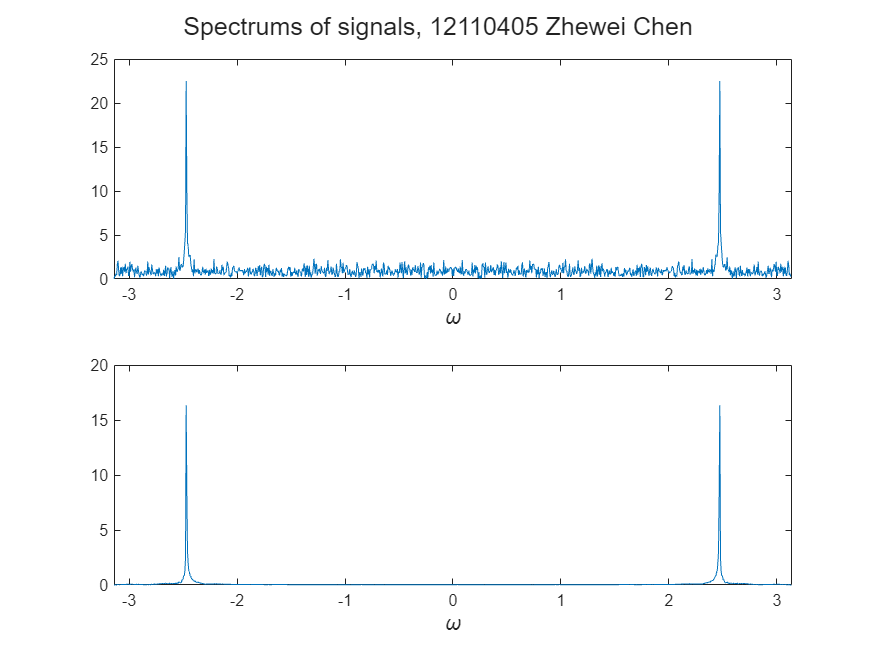

load pcm.mat
% sound(pcm)
filtered_pcm=IIRfilter(pcm);
 sound(filtered_pcm);
[X1,w1]=DTFT(pcm(100:1100),0);
[X2,w2]=DTFT(filtered_pcm(100:1100),0);

figure;
sgtitle('Spectrums of signals, 12110405 Zhewei Chen')
subplot(211);
plot(w1,abs(X1));xlabel('\omega','FontSize',12),xlim([-pi,pi])
subplot(212);
plot(w2,abs(X2));xlabel('\omega','FontSize',12),xlim([-pi,pi])

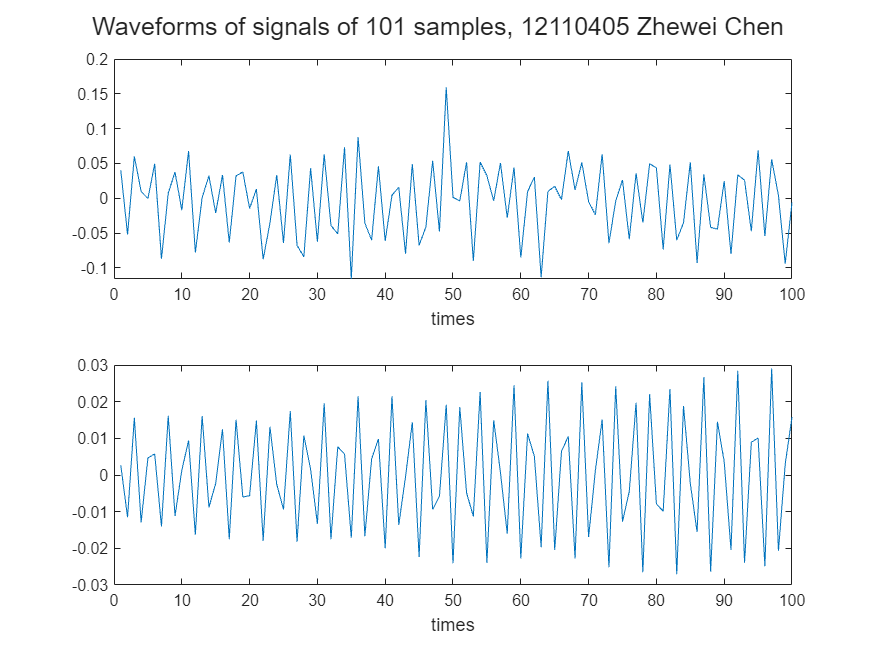



figure;
sgtitle('Waveforms of signals of 101 samples, 12110405 Zhewei Chen')
subplot(212);
plot(filtered_pcm(100:200));xlabel('times','FontSize',11),xlim([0,100])
subplot(211);
plot(pcm(100:200));xlabel('times','FontSize',11),xlim([0,100])

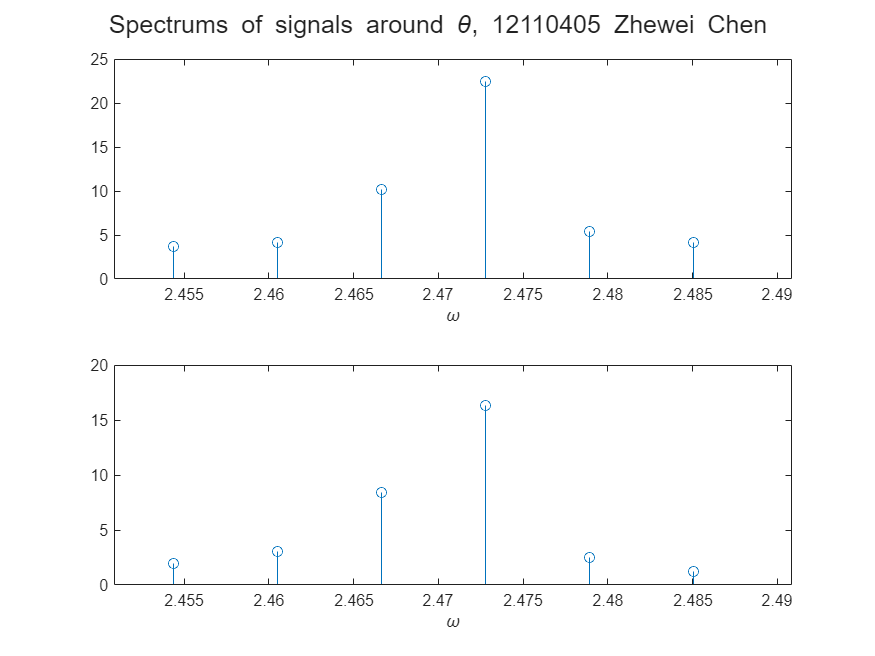


figure;
sgtitle('Spectrums of signals around \theta, 12110405 Zhewei Chen')
subplot(211);
theta=(3146/8000)*2*pi;
stem(w1,abs(X1));xlabel('\omega')
xlim([theta-0.02 theta+0.02]);
subplot(212);
theta=(3146/8000)*2*pi;
stem(w2,abs(X2));xlabel('\omega')
xlim([theta-0.02 theta+0.02]);